# Lab 4

clear;
warning("off");

## Experiment 1

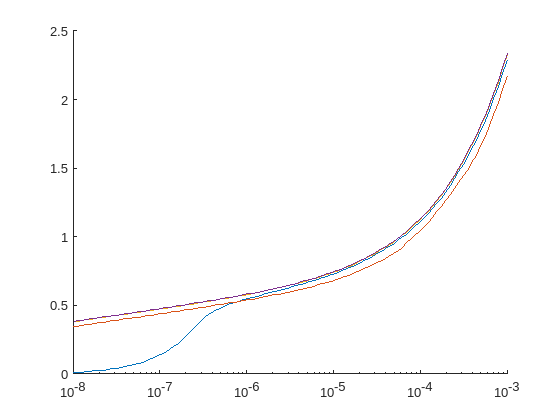

load("Ex_1_1.mat")

voltage1 = Diode_Voltage;
current1 = ch1;

load("Ex_1_2.mat")
voltage2 = Diode_Voltage;
current2 = ch1;

load("Ex_1_3.mat")

voltage3 = Diode_Voltage;
current3 = ch1;

load("Ex_1_4.mat")

voltage4 = Diode_Voltage;
current4 = ch1;
figure(1)
hold on 
plot(current1,voltage1)
plot(current2,voltage2)
plot(current3,voltage3)
plot(current4,voltage4)
set(gca, "XScale", "log");
hold off

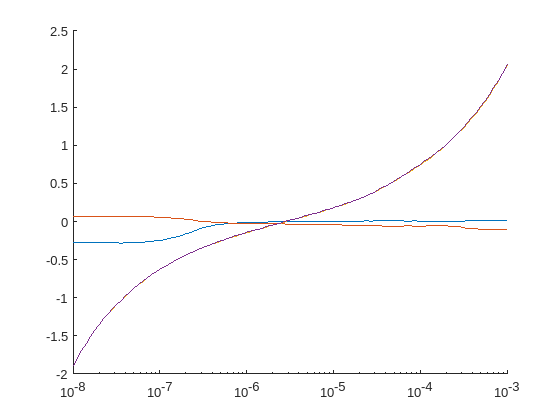

mean = (voltage1 + voltage2 + flip(voltage3) + flip(voltage4))/4;

clf;
figure(2)
hold on

plot(current1, voltage1 - mean)
plot(current2, voltage2 - mean)
plot(current3, voltage3 - mean)
plot(current4, voltage4 - mean)
set(gca, "XScale", "log");
hold off

## Experiment 2

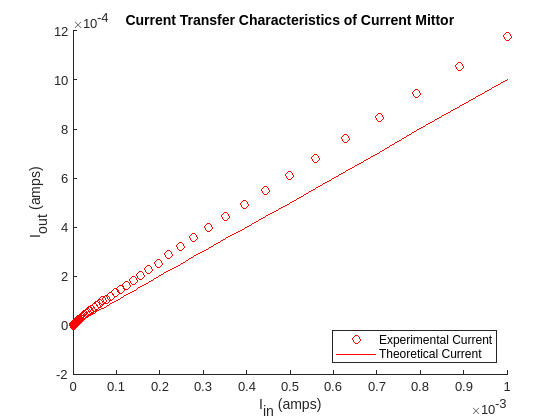

clear;
clf;
load("Ex_2_1.mat");
theo_fit = ch1;
figure(3);
hold on
loglog(ch1, MDiode_Current, 'ro');
loglog(ch1, theo_fit, 'r-');
title("Current Transfer Characteristics of Current Mittor");
xlabel("I_i_n (amps)");
ylabel("I_o_u_t (amps)")
legend("Experimental Current", "Theoretical Current", "location", "southeast");
hold off

## Experiment 3

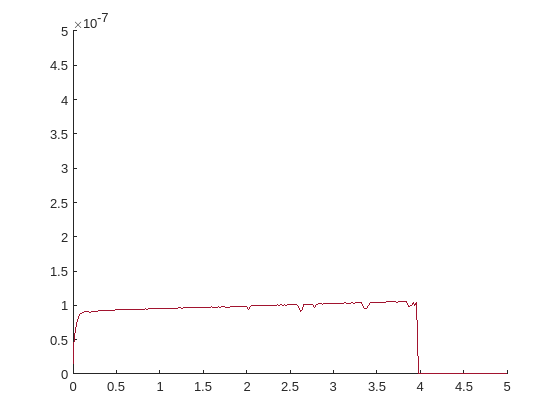

clear;
clf;
load("Ex_3.mat");
figure(4);
hold on;
semilogy(ch1_500nano);

semilogy(ch1)

Unrecognized function or variable 'ch1'.

hold off;